# Modelling project

clear 
close all
clc

## Dati

n = 25;
l = 10;
p = l^2;
r = 8;
sigma = 0.5;
P_t = 25;
raggio = 1;

## Deployment di tipo a

cont = true;
while cont 
    s = rand(n,2)*(l-1)+ 1; 
    var = ~overlapped_sensors(s,raggio);
    if var
        cont = false;
    end
end
disp("Sensori posizionati correttamente!")

Sensori posizionati correttamente!


A = init_A(s,n,p,P_t,sigma);
mu = mutual_coherence(A);
ret = 0.5*(1+1/mu);

## Creazione di Q

Computation of d_in due to the fact that eps must be included between 0 and 1/max(d_in). Done in this way there's duplicate code! Two sensors are connected if the distance between them is <= r

d_in = zeros(n,1);
for i = 1:n-1
    for j = i+1:n
        if norm(s(i,:)-s(j,:)) <= r
            d_in(i) = d_in(i)+1;
            d_in(j) = d_in(j)+1;
        end
    end 
end
R = [0,1/max(d_in)];
eps = rand(1,1)*range(R)+ min(R);
Q = init_Q(s,r,n,eps);

G=digraph(Q);

## Orthogonalization of A

global Ap tau lambda B
lambda = 1e-4;
tau = 0.7;
Ap = pinv(A);
B = (orth(A'))';
mu = mutual_coherence(B);
ret = 0.5*(1+1/mu);

## Runtime DIST

T_max = 10000;
x = zeros(n,p);
target = [1+ 9*rand(), 1+9*rand()];
y = zeros(n,1);

for i = 1:n
    d = norm(target-s(i,:));
    y(i) = RSS(d,P_t,sigma);
end
z = z_feng(y);
for t = 2:T_max
    for i = 1:n
        x_bar = zeros(1,p);
        for j=1:n
           x_bar = x_bar + Q(i,j) * x(j,:); 
        end
        x(i,:) = DIST_step(i, x_bar, x(i,:), z, B);
    end
end

## Compute final estimation

sum_agent = 0;
agent_over_x = 0;
for i = 1:n
    max_val = max(x(i,:));
    if(max_val >= 0.5)
        agent_over_x = agent_over_x+1;
        idx_max = find(x(i,:) == max_val);
        sum_agent = sum_agent + idx_max; 
    end
end
disp("Il numero di agenti che hanno almeno un valore superiore a 0.5 è: " + agent_over_x)

Il numero di agenti che hanno almeno un valore superiore a 0.5 è: 25


assert(agent_over_x <= 25 && agent_over_x >= 1);
sum_agent = sum_agent /agent_over_x;
x_i = floor(sum_agent / l) + 1;
y_i = mod(sum_agent ,l) ;

## Plot

plot_result(l,target,[x_i,y_i],s)

L'errore commesso è: 0.80355


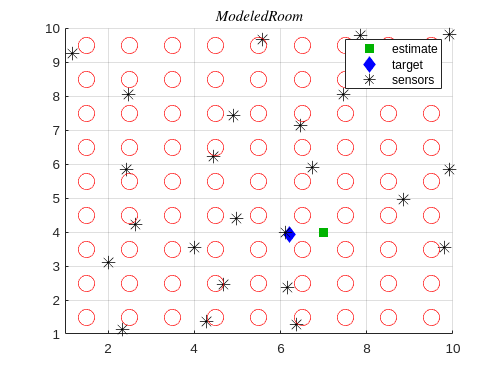

title('$$ Modeled Room $$','interpreter','latex')

## Functions

function plot_result(l,target,estimate,s)
    figure
    grid on;
    hold on;
    xlim([1 l])
    ylim([1 l])
    
    plot(estimate(1), estimate(2), 's', "color", 0.7 * [0 1 0], "markersize", 8, 'markerfacecolor', 0.7* [0 1 0]);    
    
    % Real target
    plot(target(1), target(2), 'db', "markersize", 8, 'markerfacecolor', 'b'); 
    
    %sensors
    for i = 1:length(s)
        plot(s(i,1),s(i,2),'*',"color",'k',"MarkerSize",10)
    end

    %markers
    for i=1:l-1
        for  j=1:l-1
            plot(i + .5, j + .5, 'o', "color",'r', "markersize", 12);
        end
    end
    error = norm(estimate-target);
    disp("L'errore commesso è: " + error)
    legend('estimate','target','sensors','')
end

function ret = RSS(d,P_t,sigma)
    eta = randn(1)*sigma;
    if d > 8
        ret = P_t - 58.5 - 33 *log10(d)+ eta;
    else
        ret = P_t - 40.2 - 20*log10(d)+ eta;
    end
end

function A = init_A(s,n,p,P_t,sigma)
    A = zeros(n,p);
    l = 10;

    for i = 1:p % Per ogni cella
        t = [ floor(i/l), mod(i,l) ]; % posiziono il target
        for ii = 1:n % per ogni sensore
            d = norm(s(ii,:)-t(1,:)); % calcolo la distanza dal sensore del target
            A(ii, i) = RSS(d, P_t, sigma); % e la RSS di quel sensore per quella posizione del target
        end
    end
end

function Q = init_Q(s,r,n,eps)
    Q = eps * ones(n);
    for i = 1:n-1
        for j = i+1:n
            if norm(s(i,:)-s(j,:)) > r
                Q(i,j) = 0;
                Q(j,i) = 0;
            end
        end
    end
    
    for i = 1:n
        s = sum(Q(i,:)) - eps; % eps is subtracted because Q(i,i) = eps;
        Q(i,i) = 1 - s;
    end
end
function z = z_feng(y)
    global B Ap
    z = B*Ap*y;
end
function r = IST_step(x_0,y,A)
    global tau lambda
    r = x_0 + tau*A'*(y-A*x_0);
    for i = 1:length(r)
        if(abs(r(i)) <= lambda)
            r(i) = 0;
        else
            r(i) = r(i) - sign(r(i))*lambda; 
        end
    end
end
function r = DIST_step(current, x_bar, x_0, y, A)
    global tau lambda
    r = x_bar' + tau*A(current,:)' * (y(current) - A(current,:) * x_0');
    for i = 1:length(r)
        if(abs(r(i)) <= lambda)
            r(i) = 0;
        else
            r(i) = r(i) - sign(r(i))*lambda; 
        end
    end
end
function ret = overlapped_sensors(s,raggio)
    ret = 0;    
    for i = 1:length(s)-1
        for j = i+1 : length(s)
            if(norm(s(i,:)-s(j,:)) < raggio)
                ret = 1;
                break;
            end
        end
    end    
end